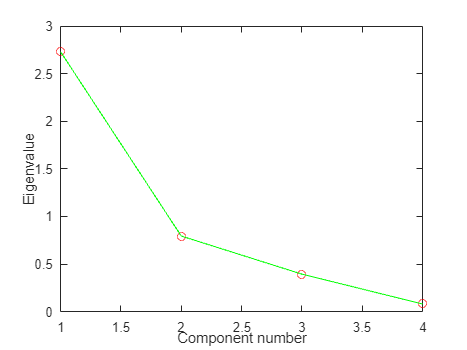

%主成分分析（第二套方法）
clear all;     %清理内存    
% load C:\MATLAB7\work\cities2003
cities2003 %调出保存的数据
mv=mean(data);
st=std(data);
[n,m]=size(data);
X=(data-mv(ones(n,1),:))./st(ones(n,1),:);
R=X'*X/(n-1);
[U,V]=eig(R);
E=transpose(rot90(U));
G=rot90(rot90(V));
eigv=diag(G);
per=100*eigv/sum(eigv);
Cum=cumsum(per);
C=sqrtm(G);
A=E*C;
Co1=A(:,1).^2;
Co2=Co1+A(:,2).^2;
Co3=Co2+A(:,3).^2;
Co4=Co3+A(:,4).^2;
Comm=[Co1,Co2,Co3,Co4];
H=A(:,1:2);
Z=X*E;
stdr=std(Z);
F=Z./stdr(ones(n,1),:);
f=F(:,1:2);
Rp=H*H';
Re=R-Rp;
figure(1);
plot(eigv,'rO');
xlabel('Component number');
ylabel('Eigenvalue');
hold on
plot(eigv,'g-');
hold off

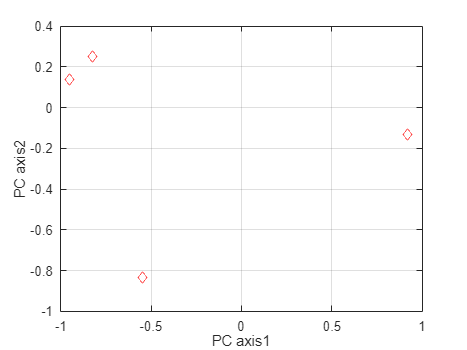

figure(2);
a1=A(:,1);a2=A(:,2);
plot(a1,a2,'rd');
xlabel('PC axis1');
ylabel('PC axis2');
grid on

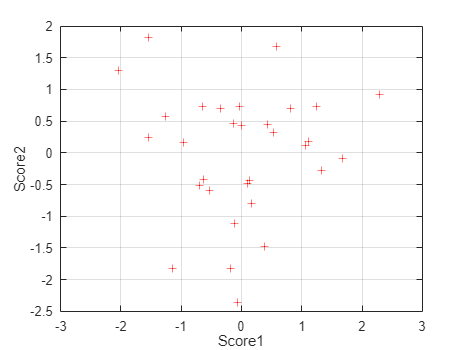

figure(3);
f1=F(:,1);f2=F(:,2);
plot(f1,f2,'r+');
xlabel('Score1');
ylabel('Score2');
grid on	


data=[data(:,1),data(:,2),data(:,3),365-data(:,4)];